Creating the Inputs, Targets, and Validations Matrices from Imported data

% Reading data matrix from the folder. Total samples is 187.
data = readmatrix("rmsdata.xlsx"); 

% Useful variables for the code
n = height(data);
w = width(data);
k = round(0.2*n,0);
t = n-k;

% Preallocation for efficiency. 
training = zeros(t,w);
testing = zeros(k,w);
random_data = zeros(n,w);

% Creating matrix of random indexes
indexes = randsample(n,n); 

% Reorganizing the data matrix rows based on created random indexes
for i = 1:n
    random_data(i,:) = data(indexes(i),:);
end

% Creating a random subset of testing data
for i = 1:k
    testing(i,:) = random_data(i,:);
end

% Creating a random set of training data
for i = 1:t
    training(i,:) = random_data(i+k,:);
end

% Preallocating for efficiency
inputs = zeros(t,4);
targets = zeros(t,1);
testinputs = zeros(k,4);
testtargets = zeros(k,1);


% Populating the inputs and target matrices
for i = 1:t
    inputs(i,1:4) = training(i,3:6);
    targets(i,1) = training(i,2);
end

% Populating the test sets 
 for i = 1:k
     testinputs(i,1:4) = testing(i,3:6);
     testtargets(i,1) = testing(i,2);
 end

**Plotting Input Data To Visualize their Relationship to the Targets**

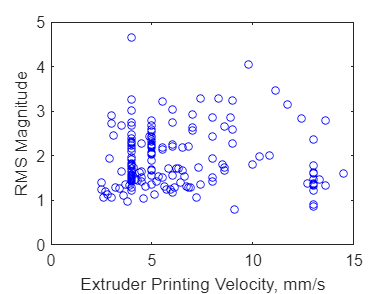

       % Checking Relationship between Velocity and Targets
plot(inputs(:,1), targets(:,1),'b o','MarkerSize',4.5);
xlabel('Extruder Printing Velocity, mm/s');
ylabel('RMS Magnitude');
xlim([0 15]);
ylim([0 5]);

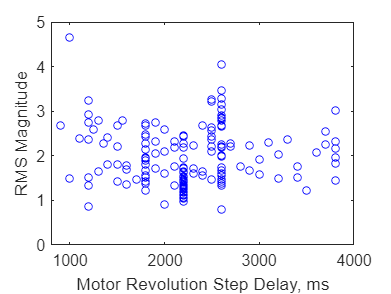


    % Checking Relationship between Delay and Targets
plot(inputs(:,2), targets(:,1),'b o','MarkerSize',4.5);
xlabel('Motor Revolution Step Delay, ms');
ylabel('RMS Magnitude');
xlim([800 4000]);
ylim([0 5]);

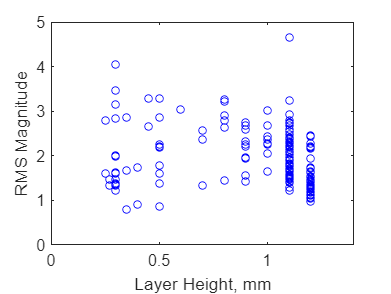


    % Checking Relationship between Layer Height and Targets
plot(inputs(:,3), targets(:,1),'b o','MarkerSize',4.5);
xlabel('Layer Height, mm');
ylabel('RMS Magnitude');
xlim([0 1.4]);
ylim([0 5]);

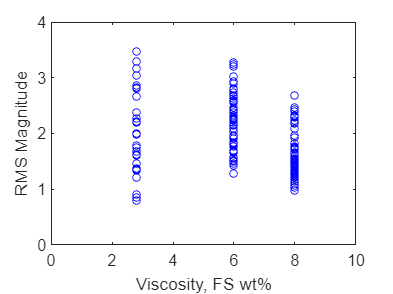


   % Checking Relationship between Viscosity and Targets
plot(inputs(:,4), targets(:,1),'b o','MarkerSize',4.5);
xlabel('Viscosity, FS wt%');
ylabel('RMS Magnitude');
xlim([0 10]);
ylim([0 4]);

**Normalizing Inputs and Test Inputs sets. Targets were not normalized**

% Prellocating for efficiency. Matrix X contains all inputs. Matrix Xtest
% contains all test set inputs
x = zeros(t,4);
xtest = zeros(k,4);

% This loop populates the matrix containing the normalized inputs
for i = 1:t    
    x(i,1) = (inputs(i,1)-min(inputs(:,1)))/(max(inputs(:,1)) - min(inputs(:,1)));
    x(i,2) = (inputs(i,2)-min(inputs(:,2)))/(max(inputs(:,2)) - min(inputs(:,2)));    
    x(i,3) = (inputs(i,3)-min(inputs(:,3)))/(max(inputs(:,3)) - min(inputs(:,3)));
    x(i,4) = (inputs(i,4)-min(inputs(:,4)))/(max(inputs(:,4)) - min(inputs(:,4)));
end


% This loop populates the matrix containing the normalized test matrix inputs
for i = 1:k
    xtest(i,1) = (testinputs(i,1)-min(testinputs(:,1)))/(max(testinputs(:,1)) - min(testinputs(:,1)));
    xtest(i,2) = (testinputs(i,2)-min(testinputs(:,2)))/(max(testinputs(:,2)) - min(testinputs(:,2)));
    xtest(i,3) = (testinputs(i,3)-min(testinputs(:,3)))/(max(testinputs(:,3)) - min(testinputs(:,3)));
    xtest(i,4) = (testinputs(i,4)-min(testinputs(:,4)))/(max(testinputs(:,4)) - min(testinputs(:,4)));
end

**Plotting Inputs after normalizing to check if data looks correct**

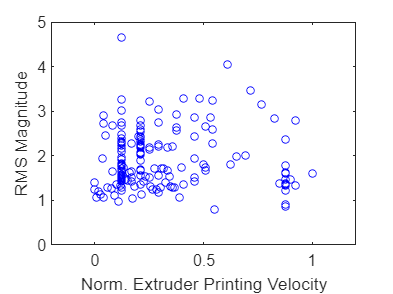

     % Checking Velocity Normalization
plot(x(:,1), targets(:,1),'b o','MarkerSize',4.5,'DisplayName','Outside Diameter');
xlabel('Norm. Extruder Printing Velocity');
ylabel('RMS Magnitude');
xlim([-0.2 1.2]);
ylim([0 5]);

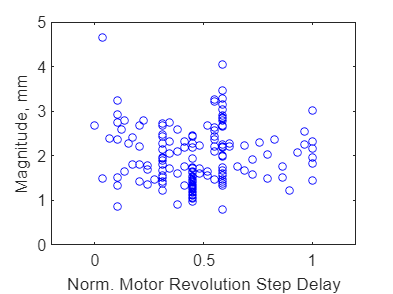


    % Checking Delay Normalization
plot(x(:,2), targets(:,1),'b o','MarkerSize',4.5,'DisplayName','Outside Diameter');
xlabel('Norm. Motor Revolution Step Delay');
ylabel('Magnitude, mm');
xlim([-0.2 1.2]);
ylim([0 5]);

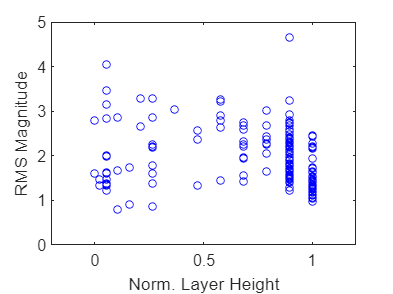


    % Checking Layer Height Normalization
plot(x(:,3), targets(:,1),'b o','MarkerSize',4.5,'DisplayName','Outside Diameter');
xlabel('Norm. Layer Height');
ylabel('RMS Magnitude');
xlim([-0.2 1.2]);
ylim([0 5]);

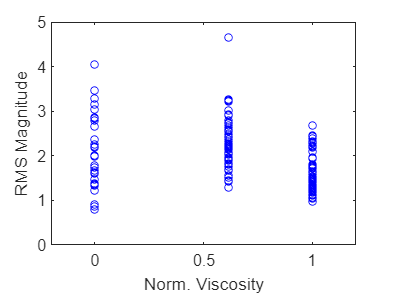


% Checking Viscosity Normalization
plot(x(:,4), targets(:,1),'b o','MarkerSize',4.5);
xlabel('Norm. Viscosity');
ylabel('RMS Magnitude');
xlim([-0.2 1.2]);
ylim([0 5]);

**Defining Input Matrix and Target Matrix for Training**


% Transpose of inputs and targets to train the network. Matrix Y1t contains
% all the targets.
xt = x';
y1t = log(targets'+1);

**Training of the NN - After RMSE Optimization Analysis **


% hidden_size defines the number of neurons and layers
hidden_size = [30,30];
net = feedforwardnet(hidden_size);

% Defining the Transfer Function at each layer
net.layers{1}.transferFcn = 'logsig'; % Can be either logsig, radbas, or purelin
%net.layers{2}.transferFcn = 'logsig';% poslin
%net.layers{3}.transferFcn = 'logsig';

% Train Function definition
net.trainFcn = 'trainlm';
net.trainParam.epochs = 1000;

% Training and Validation Rations. Here the testing Ratio can also be
% defined but the testing matrix was created earlier already. Test must be
% defined as zero, otherwise the program will draw data to create it.
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 30/100;
net.divideParam.testRatio = 0/100;

% mean-squared error as the chosen loss function
net.performFcn = 'mse'; 

% Learning rate declaration
%lr = 0.01;
%net.trainParam.lr = lr;

% Goal for the loss function
goal = 1e-6;
%net.trainParam.goal = goal;

% Number of validation checks before training stops
valchecks = 100;
net.trainParam.max_fail = valchecks;

% Training of the NN. The matrix tr contains all the indexes of the data
% points that were chosen to train and validate
[net,tr] = train(net,xt,y1t);


**Visualizing the predictions and the real values in a plot**

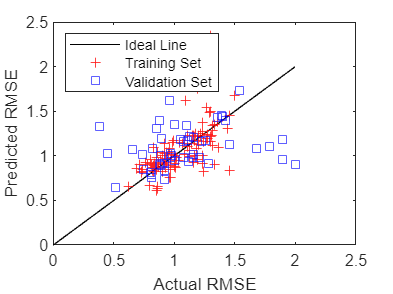

% These are the specific indexes of the values used in training,
% stored in "tr" and copied to ytrpred as a NN prediction
%on those indexed training values.
xtrain = xt(:,tr.trainInd);
ytrpred = exp(net(xtrain)-1);

yactual = y1t(:,tr.trainInd);
wtr = width(tr.trainInd);

% These are the specific indexes of the values used during
% training validation and stored in "tr". Copied to yvalpred as a NN prediction
% on those indexed validation values.
xval = xt(:,tr.valInd);
yvalpred = exp(net(xval)-1);
yvalactual = y1t(:,tr.valInd);
wval = width(tr.valInd);

plot(0:2.5, 0:2.5, 'k')
hold on
plot(yactual, ytrpred, 'r +')
plot(yvalpred, yvalactual, 'b s')
hold off 
xlim([0 2.5]);
ylim([0 2.5]);
xlabel('Actual RMSE')
ylabel('Predicted RMSE')
legend({'Ideal Line','Training Set','Validation Set'},'Location','northwest','Orientation','vertical')